clc;
x=0:500:2500;
y=500:20:800;
testwl=[519.87 561.04 603.92 640.13 684.89 730.08 785.02];
tempsIph=[56.2358	53.7333	50.3962	44.2784	40.3851	38.6056
60.581	56.132	53.351	49.7359	43.8959	42.0607
65.9829	58.6414	55.138	47.796	44.5702	45.1264
70.3283	62.9312	56.1459	51.9746	48.081	45.9678
70.8912	64.3284	57.0983	51.4254	48.7557	49.2002
72.1218	67.2831	57.2718	52.6557	50.1531	47.5381
67.6793	65.6217	58.6692	51.5505	50.8832	50.4383
59.2325	64.0706	56.1732	53.2256	51.168	49.7778
46.2807	54.234	55.3462	50.8971	51.7312	50.619
33.1062	45.0638	51.7378	48.2341	49.5135	48.9572
13.0908	25.6048	39.6206	44.9042	47.0177	49.0756
3.92105	9.76068	26.168	35.4559	45.1892	47.9701
0.59093	3.0934	7.265	19.5007	38.9667	44.8065
0.04154	0.8758	4.04599	10.8871	29.9082	37.3053
0.15988	0.71593	1.99525	7.83506	20.7383	29.0809
0.01154	0.3334	1.2792	7.56407	11.1791	21.4681];
[x,y]=meshgrid(x,y);

xj=0:100:2400;
yj=500:20:800;
[xj,yj]=meshgrid(xj,yj);
zj=interp2(x,y,tempsIph,xj,yj,'spline');
K = (1/4)*ones(2);
Tsmooth = conv2(zj,K,'same');
Tsmooth(:,end) = Tsmooth(:,end)*2;

xi=0:2400/1200:2400;      %Finial Para Gate Voltage
yi=500:300/1200:800;     %Finial Spetrum Wave Length
[xi,yi]=meshgrid(xi,yi);
zi=interp2(xj,yj,Tsmooth,xi,yi,'cubic');

xt = 500:300/1200:800;
X = 500:1:800;
A = interp1(X,RGB(:,1),xt);
B = interp1(X,RGB(:,2),xt);
C = interp1(X,RGB(:,3),xt);
yt = 100*normpdf(xt, 700, 10);
z0 = zi.';
Vt = z0*yt.';
invs = pinv(z0);
State = [1, 0.1,1.5;
    0.8,0.5,0.3;
    0.1,0.3,1]

State =     1.0000    0.1000    1.5000
    0.8000    0.5000    0.3000
    0.1000    0.3000    1.0000


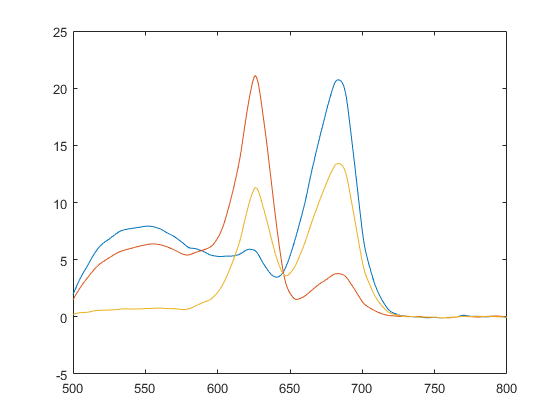

sigma = [0.44 0.52 0.5 0.45 0.42 0.4 0.35];

St_m=[];    %Initialize the test spectrum matrix
Vt_m=[];    %Initialize the response IV matrix
for i=1:1:3
    yt = State(i,1)*A+B*State(i,2)+State(i,3)*C;
    %yt = 140*sigma(i)*normpdf(xt, testwl(i), sigma(i)/2.335);
    Vti = z0*yt.';
    St_m = [St_m yt.'];
    Vt_m = [Vt_m Vti];
end
%%
%-- Vt_m add noise --%
[a b] = size(Vt_m);
V = 0:2:2400;
Amp = repmat(exp(V/2500).',1,b);
noise = wgn(a,b,1).*Amp;
Vt_m_n = floor(abs(Vt_m+noise)/4e+04*2^12)/2^12*4e+04;

anser = invs*Vt_m_n;
anser_NN = invs*Vt_m_n*0.02+St_m*0.95+St_m.*anser*0.01;
plot(xt,anser_NN);